## Relatório Projeto 2 - Matemática Computacional

### 1

### a) e b)

format Long
t = [1 2 5 7 8 9 12]

t =      1     2     5     7     8     9    12


ft = [0.9 0.4 0.18 0.2 0.22 0.27 0.36]

ft =    0.900000000000000   0.400000000000000   0.180000000000000   0.200000000000000   0.220000000000000   0.270000000000000   0.360000000000000


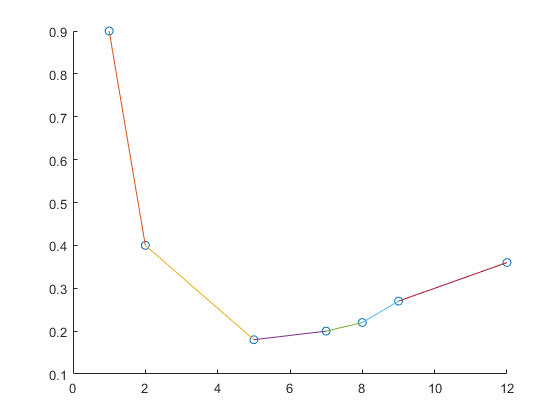

splinelinear(t,ft)

### c)

getvalue(t,ft,3) %Obtencao de f(3)

ans =    0.340000000000000


A fórmula de erro para

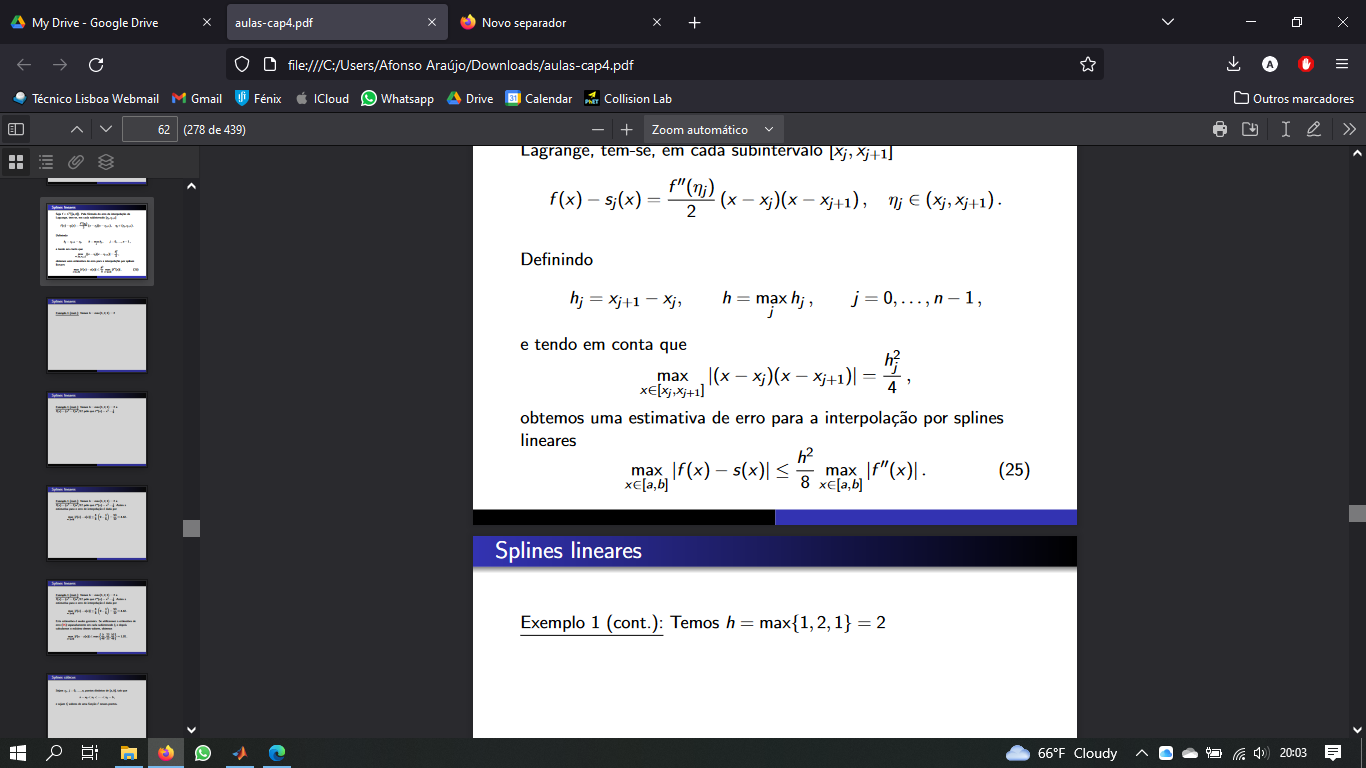

 0<f''(x)<1

calculamos os h para saber qual o máximo

%Descobrir o h máximo
n = numel(t)

n =      7


hmax = 0;
for i = 1:1:n-1
    if t(i+1)-t(i) > hmax
        hmax = t(i+1)-t(i);
    end
end

Considerando o pior dos casos para a 2 derivada de f no intervalo [1,12] podemos majorar o erro da seguinte forma:

M = ((hmax.^2)./8).*(1)

M =    1.125000000000000


Ainda assim este erro é muito grosseiro. Ao utilizar a fórmula de erro para cada subintervalo temos no ponto t=3:

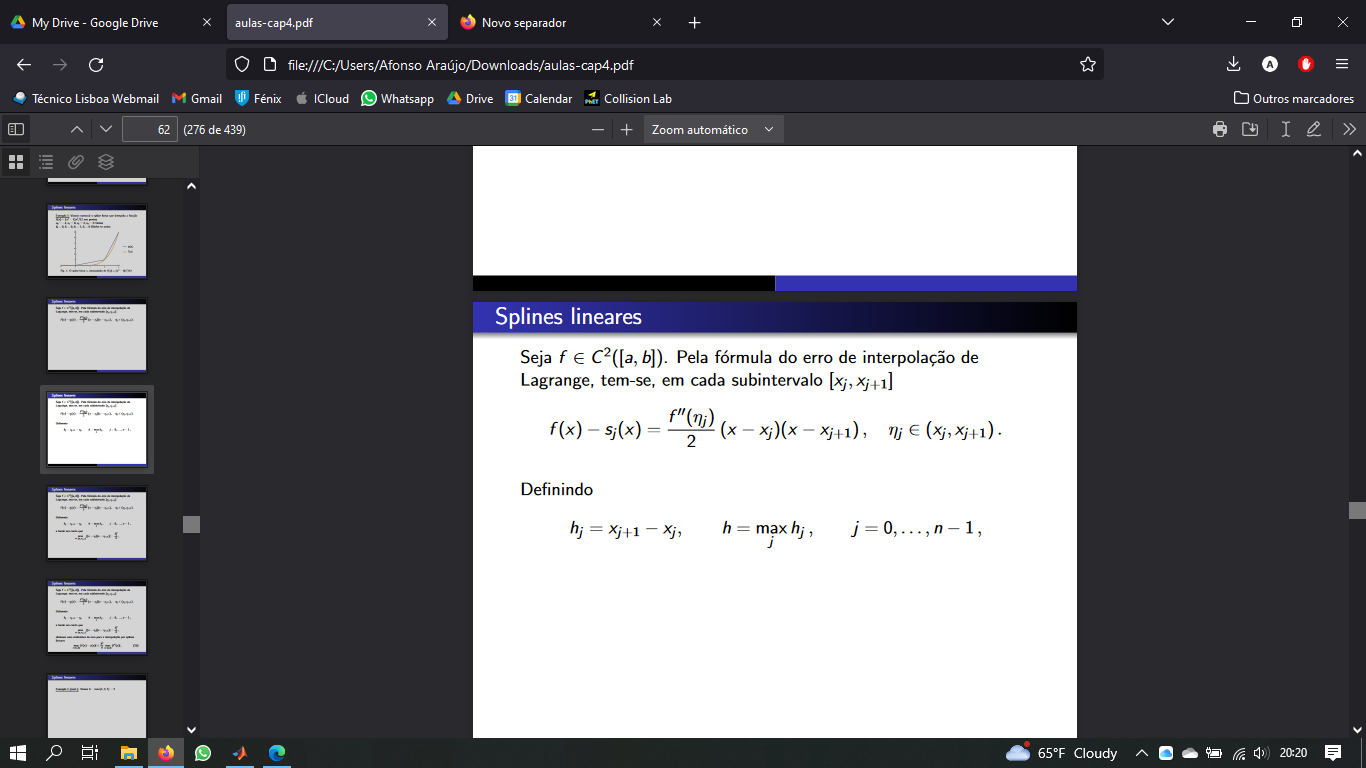

N = (1./2).*(3-2).*(3-5)

N =     -1


**Esta fórmula serve para aqui??? Serve mas a 2a derivada tem de ser especifica do ponto e nós não a temos, pq n temos função; ptt achamos que esta fórmula fica sem efeito.**

**Provavelmente n é necessario seguir com isto pq 1) nos slides considera-se um majorante de 1.92 aceitável e o nosso é muito menor e 2) não temos forma de calcular a 2a derivada especifica do intervalo, visto q n temos uma função, como dissemos acima.**

### d)

Definem-se as funções de base

phi0 = @(t) exp(-3.*t)

phi0 = function_handle with value:
    @(t)exp(-3.*t)


phi1 = @(t) exp(0.1.*t)

phi1 = function_handle with value:
    @(t)exp(0.1.*t)


phi2 = @(t) exp(-t)

phi2 = function_handle with value:
    @(t)exp(-t)



coef = minq3(t,ft,phi0,phi1,phi2)

coef =    1.078218315985077
   0.104905974210165
   1.985444480853854



f = @(t) coef(1).*phi0(t) + coef(2).*phi1(t) + coef(3).*phi2(t)

f = function_handle with value:
    @(t)coef(1).*phi0(t)+coef(2).*phi1(t)+coef(3).*phi2(t)


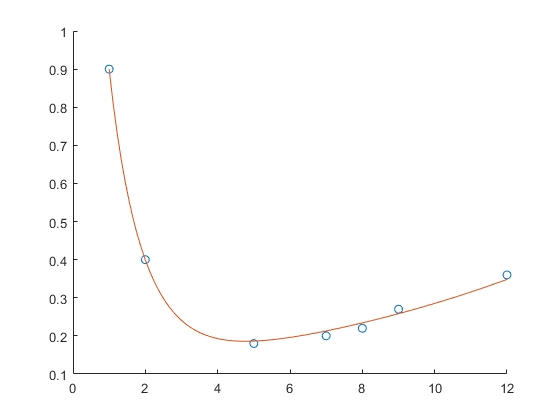


scatter(t,ft)
hold on
x = linspace(1,12,100);
plot(x,f(x))
hold off

### 2.

### a)

format long
volexact = 3.198423723387142

volexact =    3.198423723387142


g = @(x) pi.*(exp(-cos(x))).^2;
a = 1;
b = 2;

%Cálculo dos integrais para diferentes números de subintervalos
h = [];
v = [];
e = [];
ns = 10:10:100;
for i = 1:1:numel(ns)
    [v(i),h(i)] = Trapcomp(g,a,b,ns(i));
    e(i) = abs(v(i)-volexact);
end

%Representação gráfica do resultado linearizado
R = [ns' h' v' e']

R = 	1.0e+02 *

   0.100000000000000   0.001000000000000   0.032078737154889   0.000094499921018
   0.200000000000000   0.000500000000000   0.032007859222769   0.000023621988898
   0.300000000000000   0.000333333333333   0.031994735647754   0.000010498413882
   0.400000000000000   0.000250000000000   0.031990142542817   0.000005905308945
   0.500000000000000   0.000200000000000   0.031988016617114   0.000003779383242
   0.600000000000000   0.000166666666667   0.031986861800103   0.000002624566231
   0.700000000000000   0.000142857142857   0.031986165484192   0.000001928250320
   0.800000000000000   0.000125000000000   0.031985713549320   0.000001476315448
   0.900000000000000   0.000111111111111   0.031985403704685   0.000001166470813
   1.000000000000000   0.000100000000000   0.031985182074853   0.000000944840981


Rlin = [ns' log(h)' log(e)'];
scatter(Rlin(:,2), Rlin(:,3))
hold on

%Aproximação com mínimos quadrados
phi4 = @(t) (t == 0) .* 1 + (t ~= 0) .* 1;
phi5 = @(t) t;
coef = minq2(Rlin(:,2),Rlin(:,3),phi4,phi5)

coef =   -0.056484191461176
   2.000060287256971


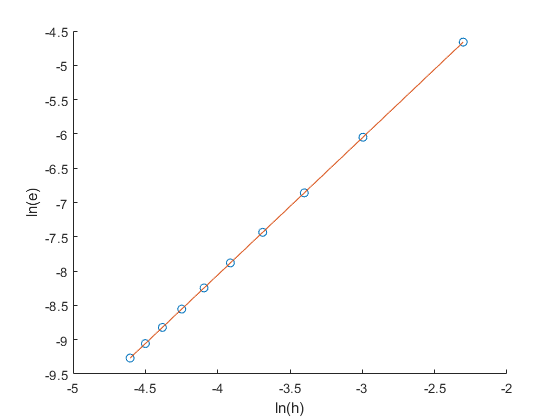

fminq = @(x) coef(1) + coef(2).*x;

%Gráfico da reta de aproximação
x = linspace(Rlin(1,2),Rlin(end,2),100);
plot(x, fminq(x))
xlabel('ln(h)')
ylabel('ln(e)')
hold off

p = 2 justificar que é o coeficiente 

### b)

format long
volexact = 3.198423723387142

volexact =    3.198423723387142


g = @(x) pi.*(exp(-cos(x))).^2;
a = 1;
b = 2;

%Cálculo dos integrais para diferentes números de subintervalos
h = [];
v = [];
e = [];
ns = 10:10:100;
for i = 1:1:numel(ns)
    [v(i),h(i)] = Simpcomp(g,a,b,ns(i));
    e(i) = abs(v(i)-volexact);
end

%Representação gráfica do resultado linearizado
R = [ns' h' v' e']

R = 	1.0e+02 *

   0.100000000000000   0.001000000000000   0.031984175249417   0.000000061984454
   0.200000000000000   0.000500000000000   0.031984233245396   0.000000003988475
   0.300000000000000   0.000333333333333   0.031984236441902   0.000000000791970
   0.400000000000000   0.000250000000000   0.031984236982832   0.000000000251039
   0.500000000000000   0.000200000000000   0.031984237130960   0.000000000102912
   0.600000000000000   0.000166666666667   0.031984237184219   0.000000000049652
   0.700000000000000   0.000142857142857   0.031984237207063   0.000000000026808
   0.800000000000000   0.000125000000000   0.031984237218154   0.000000000015717
   0.900000000000000   0.000111111111111   0.031984237224058   0.000000000009813
   1.000000000000000   0.000100000000000   0.031984237227432   0.000000000006439


Rlin = [ns' log(h)' log(e)'];
scatter(Rlin(:,2), Rlin(:,3))
hold on

%Aproximação com mínimos quadrados
phi4 = @(t) (t == 0) .* 1 + (t ~= 0) .* 1;
phi5 = @(t) t;
coef = minq2(Rlin(:,2),Rlin(:,3),phi4,phi5)

coef =   -2.800377594103114
   3.986341214944837


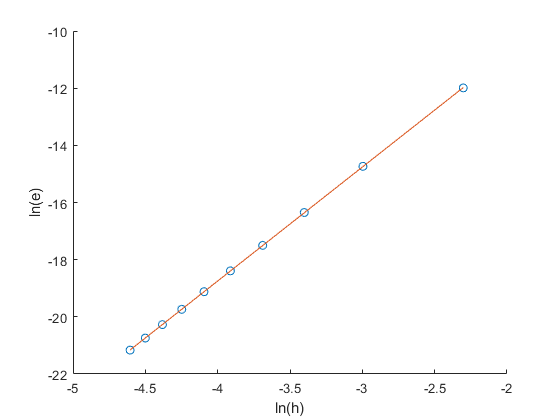

fminq = @(x) coef(1) + coef(2).*x;

%Gráfico da reta de aproximação
x = linspace(Rlin(1,2),Rlin(end,2),100);
plot(x, fminq(x))
xlabel('ln(h)')
ylabel('ln(e)')
hold off

p =~ 4 justificar a diferença dos ps nos diferentes métodos

### c)

Queremos Erro de V < 10e-7

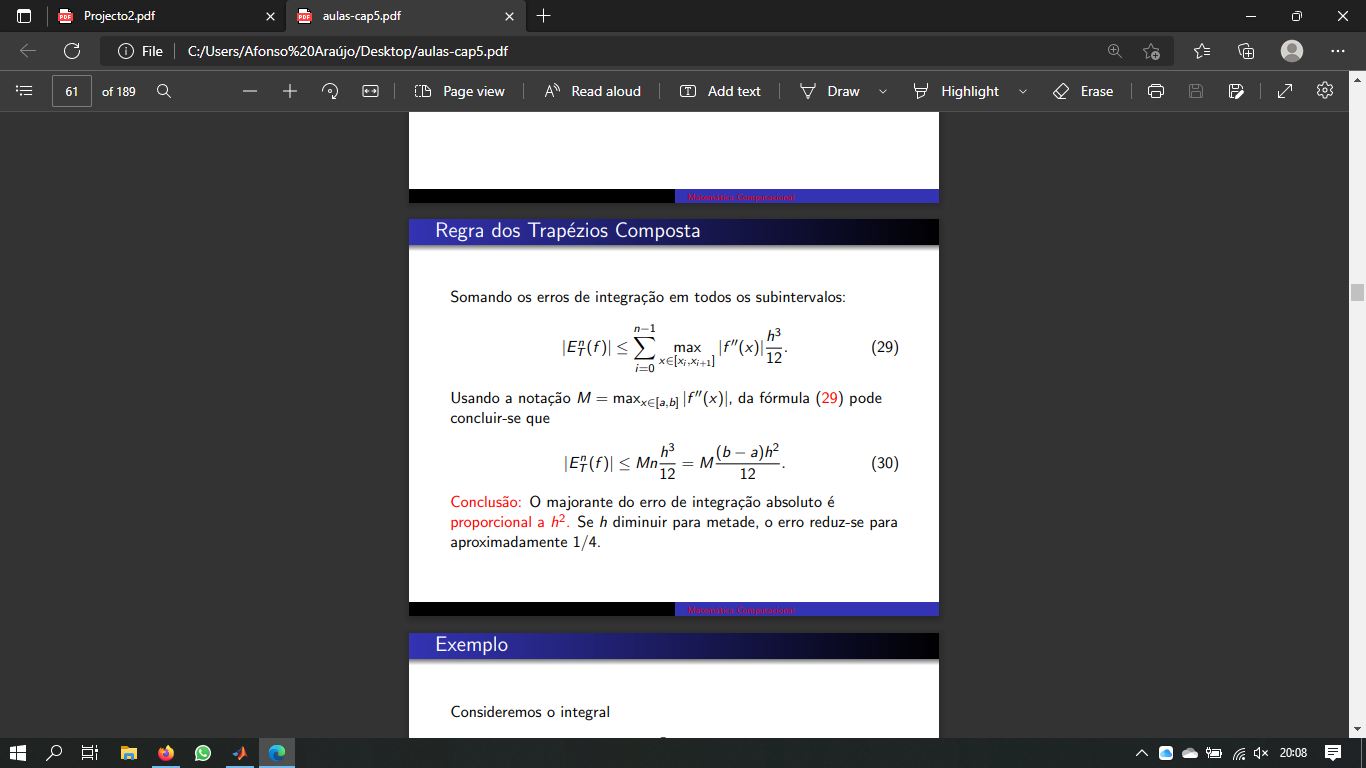

a=1;
b=2;
E = 10^-7;

M = máximo de f'' no intervalo [a,b]

g = @(x) pi.*(exp(-cos(x))).^2;
d1g = @(x) pi.*(exp(-2.*cos(x))).*2.*sin(x);
d2g = @(x) 2.*pi.*(2.*exp(-2.*cos(x)).*sin(x).^2+exp(-2.*cos(x)).*cos(x));
d3g = @(x) 2.*pi.*(4.*exp(-2.*cos(x)).*sin(x).^2+3.*exp(-2.*cos(x)).*sin(2.*x)-exp(-2.*cos(x)).*sin(x));

Falta mostrar que a 3 derivada é positiva e por isso o máximo etc...

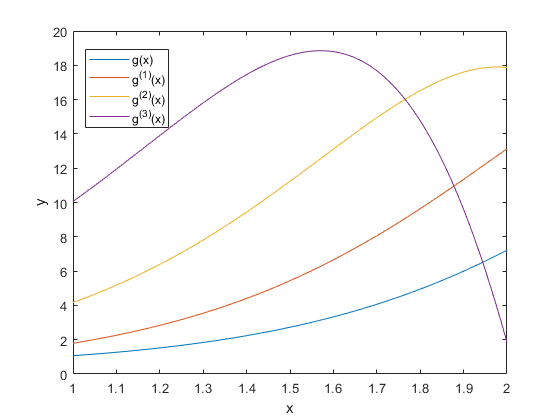

x = linspace(a,b,100);
plot(x,g(x))
hold on
plot(x,d1g(x))
plot(x,d2g(x))
plot(x,d3g(x))
legend({'g(x)','g^{(1)}(x)','g^{(2)}(x)','g^{(3)}(x)'},'Location','best')
xlabel('x')
ylabel('y')
hold off


M = d2g(b)

M =   17.872466717324365



%E = (M*(b-a)*h^2)/12 escrever latex
%rearanjado
h = sqrt(12*E/(M*(b-a)));
N = (b-a)/h;
ceil(N)

ans =         3860


Para verificar

[vol,h] = Trapcomp(g,a,b,3860);
erro = abs(volexact-vol)

erro =      6.341372893459152e-08


erro<=E

ans = logical
   1


Se fossem menos

[vol,h] = Trapcomp(g,a,b,3000);
erro = abs(volexact-vol)

erro =      1.049821500842540e-07


erro<=E

ans = logical
   0


Podemos mostrar numa tabela qual seria o mínimo experimentalmente porque o stor das praticas disse que nao se usava teoria em trabalhos computacionais.

Uma tabela com os valores e dados logical a dizer se verifica ou não.

Para os pontos de interesse, sabemos que por volta de 1000 é o ponto de viragem

%pontos de interesse
format longG
vol = [];
erro = [];
logic = [];
i = 1;
for n = 3000:100:3900
    [vol(i),~] = Trapcomp(g,a,b,n);
    erro(i) = abs(volexact-vol(i));
    logic(i) = erro(i)<=E;
    i = i+1;
end
n = 3000:100:3900;
R = [n' vol' erro' logic']

R =                       3000          3.19842382836929      1.04982150084254e-07                         0
                      3100          3.19842382170549      9.83183472413884e-08                         1
                      3200           3.1984238156566      9.22694614047259e-08                         1
                      3300          3.19842381014925      8.67621028355359e-08                         1
                      3400          3.19842380512065      8.17335030767197e-08                         1
                      3500          3.19842380051688      7.71297385959713e-08                         1
                      3600          3.19842379629141      7.29042657354739e-08                         1
                      3700          3.19842379240389      6.90167496486538e-08                         1
                      3800          3.19842378881922      6.54320801984909e-08                         1
                      3900          3.1984237855067

No intuito de refinar a pesquisa podemos fazer o mesmo para uns pontos mais próximos da solução:

%pontos de interesse
vol = [];
erro = [];
logic = [];
i = 1;
for n = 3000:10:3100
    [vol(i),~] = Trapcomp(g,a,b,n);
    erro(i) = abs(volexact-vol(i));
    logic(i) = erro(i)<=E;
    i = i+1;
end
n = 3000:10:3100;
R = [n' vol' erro' logic']

R =                       3000          3.19842382836929      1.04982150084254e-07                         0
                      3010           3.1984238276729      1.04285756918898e-07                         0
                      3020           3.1984238269834      1.03596259126704e-07                         0
                      3030          3.19842382630073      1.02913590094289e-07                         0
                      3040          3.19842382562477        1.022376285853e-07                         0
                      3050          3.19842382495547      1.01568326194013e-07                         0
                      3060           3.1984238242927      1.00905562572251e-07                         0
                      3070          3.19842382363641       1.0024926755392e-07                         0
                      3080           3.1984238229865      9.95993589825162e-08                         1
                      3090          3.1984238223428

Pesquisa mais refinada:

%pontos de interesse
vol = [];
erro = [];
logic = [];
i = 1;
for n = 3070:1:3080
    [vol(i),~] = Trapcomp(g,a,b,n);
    erro(i) = abs(volexact-vol(i));
    logic(i) = erro(i)<=E;
    i = i+1;
end
n = 3070:1:3080;
R = [n' vol' erro' logic']

R =                       3070          3.19842382363641       1.0024926755392e-07                         0
                      3071          3.19842382357113      1.00183984663715e-07                         0
                      3072          3.19842382350592      1.00118777268676e-07                         0
                      3073          3.19842382344076      1.00053621387985e-07                         0
                      3074          3.19842382337569       9.9988544555174e-08                         1
                      3075          3.19842382331067      9.99235232335138e-08                         1
                      3076           3.1984238232457      9.98585605316293e-08                         1
                      3077          3.19842382318081      9.97936648872155e-08                         1
                      3078          3.19842382311598      9.97288340798264e-08                         1
                      3079           3.198423823051

Podemos ver que na última tabela o primeiro valor de n a verificar a condição exigida é 3074. Logo, são necessários 3074 subintervalos em [a,b] para que o integral dado pela Regra dos Trapézios Composta tenha um erros inferior a 10e-7.

### Definição de Funções

%Calculo do integral pela regra de Simpson Composta
function [res, h] = Simpcomp(f,a,b,n)
if mod(n,2) ~=0 %requer número de intervalos pares
    n = n+1;
end
h = abs(a-b)/n;
int = linspace(a,b,n+1);
res = (h/3)*(f(int(1))+f(int(end)));
for i = 2:1:n     %só os pontos interiores
    if mod(i,2) == 0    %a contagem no matlab começa no 1 por isso está trocado
        res = res + (4*h/3)*f(int(i));    %termos ímpares
    else
        res = res + (2*h/3)*f(int(i));    %termos pares
    end
end
end

%Calculo do integral pela regra dos Trapézios Composta
function [res,h] = Trapcomp(f,a,b,n)
int = linspace(a,b,n+1);
h = abs(a-b)/n;
res = 0;
for i = 1:1:n
    res = res + (f(int(i))+f(int(i+1))).*h/2;
end
end

%Função dos mínimos quadrados para 2 funções de base
function v = minq2(t,ft,phi0,phi1)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t))];
v = A\b;
end

%Função dos mínimos quadrados para 3 funções de base
function v = minq3(t,ft,phi0,phi1,phi2)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t)) dot(phi0(t),phi2(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t)) dot(phi1(t),phi2(t));
     dot(phi2(t),phi0(t)) dot(phi2(t),phi1(t)) dot(phi2(t),phi2(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t));
     dot(ft,phi2(t))];
v = A\b;
end

%Função produto interno
function [c] = dot(a,b)
n = numberofelements(a);
c = 0;
for i = 1:1:n
    c = c + a(i)*b(i);
end
end

%Função que encontra uma aproximação para um dado t recorrendo ao spline linear
function [b] = getvalue(t,ft,a)
n = numel(t);      
min = t(1);     %encontrar entre que pontos está o 'a' pedido
for i = 1:1:n
    if t(i) > a
        min = t(i-1);
        max = t(i);
        break
    end
end
b =  ft(min)+(ft(max)-ft(min)).*(a-min)./(max-min);
end

%Função que desenha o spline linear
function [] = splinelinear(t,ft)
scatter(t,ft)
hold on
x = linspace(1,12,100);
n = numel(t);
for i = 1:1:n-1
    s = @(x) ft(i)+(ft(i+1)-ft(i)).*(x-t(i))./(t(i+1)-t(i));
    fplot(s,[t(i),t(i+1)])
end
hold off
end